# Neural Network model for BEV battery onboard temperature estimation and hardware deployment

This example shows how to generate data and train a neural network for battery temperature estimation, and how to generate C-code for deployment on hardware. The battery temperature is modeled using neural networks, based on the training data generated from a detailed battery-physics (plant) model. The trained neural network is verified for accuracy.

# Introduction

This example shows how to predict the temperature of an automotive battery pack by using neural networks. In an automotive battery pack, the pack voltage, current, and temperature sensors send measurement signals to the Battery Management System (BMS). These signals are important for the battery control and the logic implementation. The temperature sensor is expensive and cannot be easily placed in a large battery pack. A numerical method to estimate battery temperature helps replacing the sensor. This example shows how to train a neural network based on battery physics (model), and how to convert the network into C code for onboard battery temperature prediction. This enables cost savings by eliminating the need of a thermocouple and an onboard numerical estimation of the battery temperature based on the voltage and current sensor measurements. 

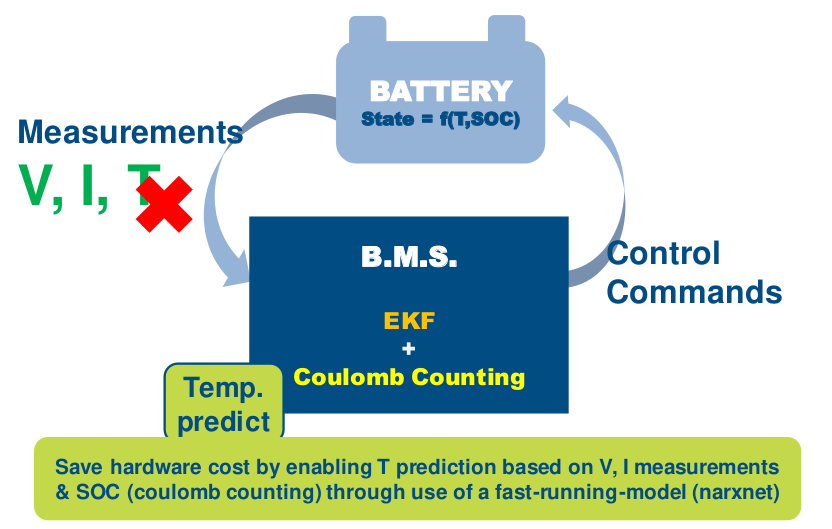

# Battery Pack Data 

To generate training data for neural network, this example uses a detailed physics based model for the battery pack. If real hardware data is available, this physics based simulation is not required. The `Battery_TempPredUsingNN_PhysicsModel` SLX file contains the battery plant model for training or drive-profile runs. The plant model is a slightly modified version (no feedback or controls) of the `ee_lithium_pack_cooling` Simscape™ Electrical™ example. 

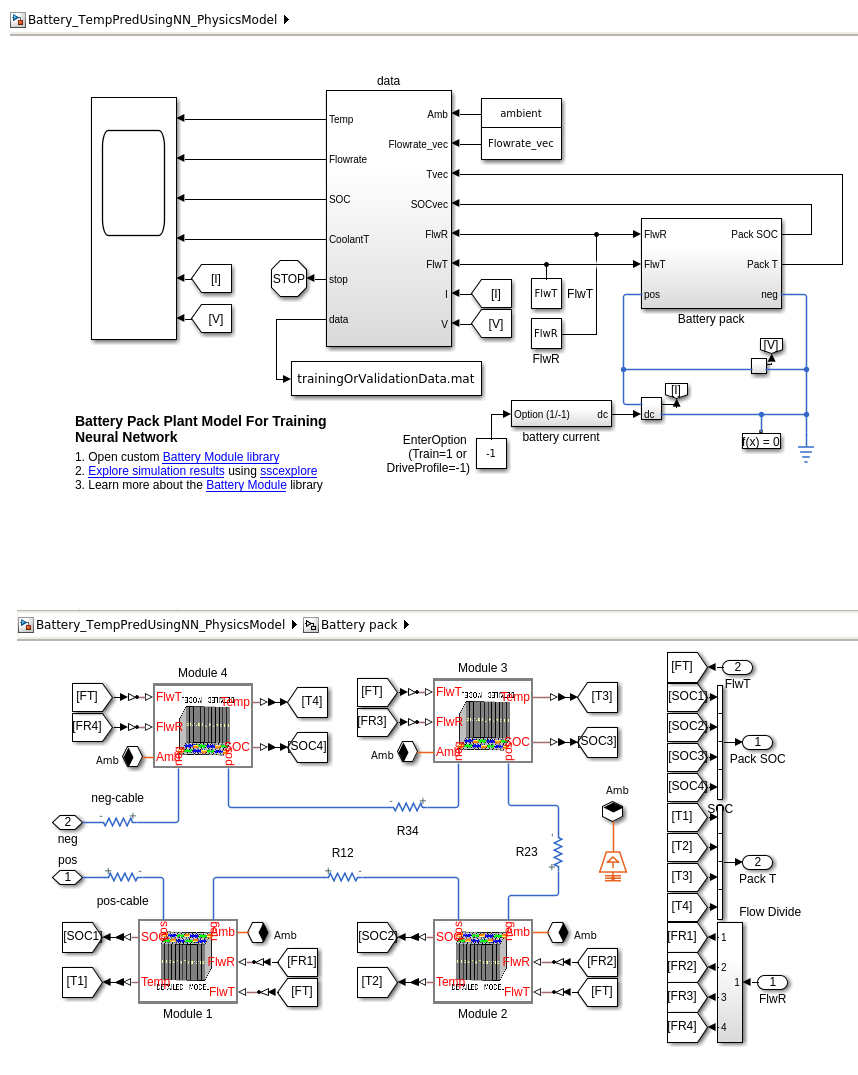

The battery pack consists of several battery modules, which are combinations of cells in series and parallel. Each battery cell is modeled using the `Battery (Table-Based)` Simscape Electrical block.  In this example, the initial temperature and the state-of-charge are the same for all the cells. Four battery modules, three similar and one differing from the other three, are connected in series to simulate a battery pack. The results in this example assume an initial ambient temperature equal to 25 degree Celsius. The coolant flowrate in the battery pack is constant and the model either generates the training data or visualizes the drive-profile runs. Use the `EnterOption (Train=1 or DriveProfile=-1)` block to train the data or to visualize the drive-profile runs.

# Generate Training Data

The battery state is defined by its temperature and the state of charge. The power demand P is the DC current demand multiplied by the battery instantaneous voltage V and it is an external signal to the model. The battery state estimation requires information on the battery initial temperature. The neural network is based on the power demand (input), battery state-of-charge (input) and temperture (output, feedback). The battery state-of-charge for the neural network is calculated using coulomb counting that integrates the DC current passing through the battery over time. A neural network with these attributes is defined for training. It is important to train the neural network model on data that spans all its intended usage. In this example, the model is trained for a constant coolant flowrate and different charge-discharge rates. Multiple constant current charge-discharge profiles are simulated to evaluate the temperature response during charge-discharge reversal, for the entire state-of-charge range. 

The training data is generated by running a battery plant model, at a constant coolant flowrate, for a number of fixed charge and discharge cycles. The temperature recorded for training is the instantaneous battery current I, voltage V, state of charge SOC, and temperature T. To define a constant maximum flowrate, the input `FlwR `is set to 1. To run the plant model and generate training data, this example uses a fixed time step of 1 second. This is the time step at which the neural network would be trained and subsequently deployed. 

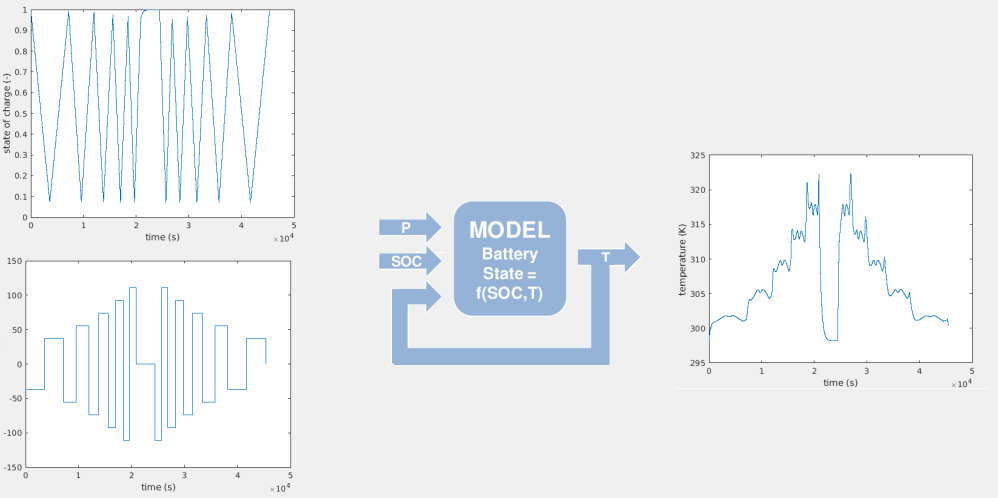

This figure shows the training process, the DC current, and state-of-charge profiles used for generating the training data. As the battery is charged and discharged, it produces heat that is reflected in its measured temperature. The battery current, temperature, state-of-charge, voltage and flowrate data are recorded and stored in the `Battery_TempPredUsingNN_TrainingData` MAT file. To load the data at the MATLAB command prompt, enter:

tempRef=298;
dataTrain=load('Battery_TempPredUsingNN_TrainingData.mat');
% data in columns 1, 2, 3, 4,and 5 contain battery pack current,
% temperature, state of charge, voltage, and FlwR parameter. In this
% example, FlwR is not used.
dataPow=dataTrain.data.Data(:,1)'.*dataTrain.data.Data(:,4)';
dataTmp=dataTrain.data.Data(:,2)'-tempRef;
dataSOC=dataTrain.data.Data(:,3)';

The next step is to normalize the training data. The temperature data, `dataTmp`, has already been reduced by 298K as a first step for normalization. The state-of-charge values are between 0 and 1 and do not require normalization. The `dataPow` and `dataTmp` parameters are normalized.

% Normalize output data, Temperature T
mu_tmp=mean(dataTmp,2);
sig_tmp=std(dataTmp,0,2);
dataTmp=(dataTmp-mu_tmp)/sig_tmp;
% Normalize input data for Power, P
mu_pow=mean(dataPow,2);
sig_pow=std(dataPow,0,2);
dataPow=(dataPow-mu_pow)/sig_pow;
% Convert data to cell arrays
data_NARX_Y=dataTmp;
data_NARX_X2=[dataPow;dataSOC];
cellArrayNARX_X=con2seq(data_NARX_X2);
cellArrayNARX_Y=con2seq(data_NARX_Y);

You can now use the training data to train the network. 

# Train Neural Network

The training is carried out using steps outlined in [Design Time-Series NARX Feedback Neural Networks](https://www.mathworks.com/help/deeplearning/ug/design-time-series-narx-feedback-neural-networks.html) and the same is described below.

## Training

To store the trained network, the parameters for data normalization, and the training error, first define a cell array. 

% Cell array to save final trained network
trainedNet=cell(3,1);

Then define the number of `delay time steps` and `hidden layer size` for the neural network. Divide the training data set into train, validate, and test data sets in a ratio of 80/10/10 percentage, respectively.

% Define hidden layer size and delays
delaySteps=2;
hiddenLayerSize=24;
trainFcn='trainlm';  % Optimization Algorithm.
inputDelays=1:(delaySteps+1);
feedbackDelays=1:(delaySteps+1);
% Set network parameters
narx_net=narxnet(inputDelays,feedbackDelays,hiddenLayerSize,'open',trainFcn);
narx_net.trainParam.min_grad=1e-7;
[p,Pi,Ai,t]=preparets(narx_net,cellArrayNARX_X,{},cellArrayNARX_Y);
narx_net.divideParam.trainRatio=80/100;
narx_net.divideParam.valRatio=10/100;
narx_net.divideParam.testRatio=10/100;

Train the network for open loop and closed loop predictions. 

% Train the model, NARX open loop
narx_net=train(narx_net,p,t,Pi);
yp=sim(narx_net,p,Pi);
errOpenLoop=cell2mat(yp)-cell2mat(t);
% Convert model to closed loop
narx_net_closed=closeloop(narx_net);
[p1,Pi1,Ai1,t1]=preparets(narx_net_closed,cellArrayNARX_X,{},cellArrayNARX_Y);
yp1=narx_net_closed(p1,Pi1,Ai1);
errClosedLoop=((cell2mat(t1)-cell2mat(yp1)).*sig_tmp+mu_tmp);

Update the `trainedNet` cell array to store the trained network, training errors, and the parameters used for training data normalization.

% Save network
trainedNet{3,1}=[mu_tmp,sig_tmp,mu_pow,sig_pow,tempRef]; % data for normalization
trainedNet{2,1}=[errOpenLoop,errClosedLoop]; % save open and closed loop errors
trainedNet{1,1}=narx_net_closed; % save network
save Battery_TempPredUsingNN_trainedNet.mat trainedNet

`Hidden layer size` of 24 is chosen based on some runs carried out with different hidden layer sizes. Open and closed loop errors were used as an indication of the fit and the appropiate hidden layer size selected. With a modeling time-step of 1s and a `delay` of 3, temperature feedback of last 3s was found to be sufficient in obtaining a good trained model. The `narx_net.trainParam.min_grad` parameter was set to default 1e-7, but can  be relaxed to acheive faster training and an approximate fit. In this example, the default training function, [Levenberg-Marquardt](https://www.mathworks.com/help/deeplearning/ref/trainlm.html), was selected for training. You can learn more about the training functions at [Choose a Multi-Layer Neural Network Training Function](https://www.mathworks.com/help/deeplearning/ug/choose-a-multilayer-neural-network-training-function.html).

## Training Validation & Verification

To verify the accuracy of the training, plot the temperature prediction from the `trainedNet` network and compare it with the entire training data set. To compare the training data set with the temperature prediction between the trained network `trainedNet` and a pre-trained network stored in the `Battery_TempPredUsingNN_preTrained` MAT file, run these commands.

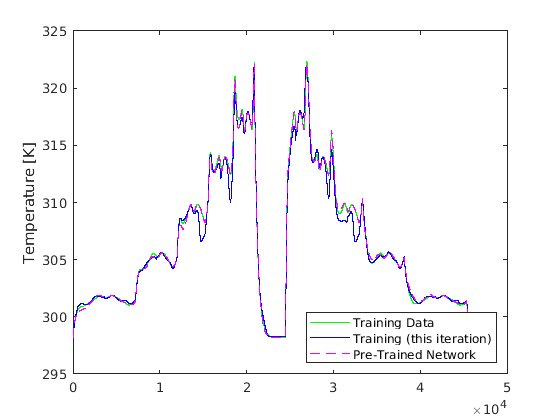

% Evaluate current trained model results
verifyNetwork=trainedNet{1,1};
[pv,Piv,Aiv,tv]=preparets(verifyNetwork,cellArrayNARX_X,{},cellArrayNARX_Y);
yp_v=verifyNetwork(pv,Piv,Aiv);
% Compare Model against a pre-trained network
plotNetTrained=load('Battery_TempPredUsingNN_preTrained.mat');
verifyNetwork=plotNetTrained.trainedNet{1,1};
[pv0,Piv0,Aiv0,tv0]=preparets(verifyNetwork,cellArrayNARX_X,{},cellArrayNARX_Y);
yp_v0=verifyNetwork(pv0,Piv0,Aiv0);
% Plot Training Data, Current Network and a pre-Trained Network
figure(1);
TS=size(tv,2);
plot(1:length(dataTrain.data.Data(:,2)'),dataTrain.data.Data(:,2)','g');
hold on
plot(1:TS,cell2mat(yp_v).*sig_tmp+mu_tmp+tempRef,'b');
hold on
plot(1:TS,cell2mat(yp_v0).*sig_tmp+mu_tmp+tempRef,'m--');
hold off
ylabel('Temperature [K]')
xlabel('Time [s]')
legend('Training Data','Training (this iteration)','Pre-Trained Network','Location','southeast')

title('Trained Model comparison with Training Data')

For a given number of `hidden layer size` and `delays`, you might obtain different results each time you train the network. This is due to random initalization of the inital weights in the network. To visualize and select the most appropiate network, run the above script for different number of `hidden layer size`, `delays`, and iterations and store the `trainedNet` network in a file. To check the closed loop performance, plot the final network with the data itself. The errors, or the root-mean-square errors, for the open loop and the closed loop model are a good indicator of the accuracy. To check for potential overfit and underfit scenarios, perform a visual examination of the plot of the final network with the training data. For more information on fitting networks, see [Improve Shallow Neural Network Generalization And Avoid Overfitting](https://www.mathworks.com/help/deeplearning/ug/improve-neural-network-generalization-and-avoid-overfitting.html). 

# Application - Drive Profile Simulations

The final step is to use the trained network, predict a completely different power demand, and compare the temperature predictions between the neural network and the battery plant model. This example combines multiple drive profiles to make a larger, agressive profile and validate the model effectiveness. The temperature predictions from the neural network model are compared with preditions obtained from the physics based battery plant model. The data from the physics based battery plant model is stored in MAT file. Three different cases are simulated and the data from physics model is stored in 3 different MAT files:

- Battery_TempPredUsingNN_FTP72_NEDC_US06_FTP72_SC03

- Battery_TempPredUsingNN_US06_NEDC_LA92_NYCC_FTP72

- Battery_TempPredUsingNN_WLTP1_WLTP2_WLTP3_US06_NEDC

The neural network input only includes the power demand to the battery pack. This input is the same for both the battery plant model and the neural network. The other input to the neural network is the battery `state-of-charge` (SOC) that is calculated using coulomb counting based on the input power (or current) demand. The initial state for `temperature` in the neural network, based on the number of delays (3 in this example), is defined as the ambient temperature. In real world, you can obtain this value from any other onboard temperature sensor for the ambient conditions. The power demand, or the DC current demand, is based on different vehicle drive profiles. 

% Load data for the trained network
% Here, a pre-trained network is used; to use your own trained network,
% change the name of the *.mat file
alpha=load('Battery_TempPredUsingNN_preTrained.mat');

% Copy the normalization variables and the trained network from the data
normalizationVar=alpha.trainedNet{3,1};
useNetwork=alpha.trainedNet{1,1};
mu_tmp=normalizationVar(1,1);
sig_tmp=normalizationVar(1,2);
mu_pow=normalizationVar(1,3);
sig_pow=normalizationVar(1,4);
tempRef=normalizationVar(1,5);

Then, define the simulation `time step`, `battery cell capacity`, `number of parallel cells` in the system, and the `delay` of the neural network.

% Setup battery parameters for the neural network
neuralNetTS=1;   % Time step at which model is trained (s)
cellCapacity=20; % Ahr (25 degC)
numParallelCells=2;
nDelay=delaySteps+1;
ambient=298;     % Ambient temperature in K
simulationParam=[neuralNetTS,cellCapacity,nDelay,ambient,numParallelCells];

The battery plant model output for drive profiles is loaded and the neural network receives power (current times voltage) as the input. The state-of-charge is updated for the timeseries by integrating current variation over time. The first three timesteps for the temperature, that represent the 3 timestep delays, are set to ambient and the battery state-of-charge is equal to 1. This example uses 3 different large composite drive-profiles:

(1) FTP72, NEDC, US06, FTP72, SC03 drive profiles run continuously one after another

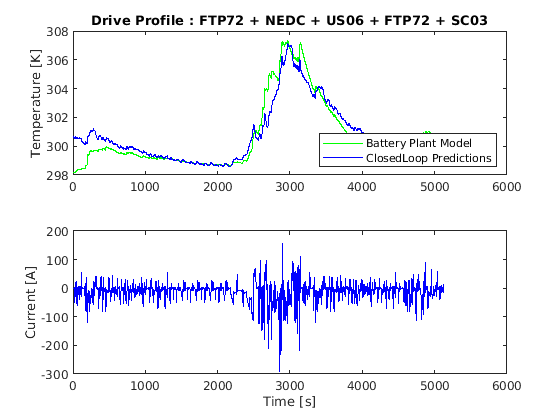

% Evaluate Profile : FTP72 + NEDC + US06 + FTP72 + SC03
driveProfile_X=load('Battery_TempPredUsingNN_FTP72_NEDC_US06_FTP72_SC03.mat');
[plotData1,...
 plotData2,...
 plotData3,...
 p3,Pi3,Ai3,t3] = Battery_TempPredUsingNN_driveProfile(...
                  simulationParam,...
                  driveProfile_X,...
                  alpha);
figure(2)
subplot(2,1,1)
plot(plotData1(1,:),plotData1(2,:),'g');
hold on
plot(plotData2(1,:),plotData2(2,:),'b');
hold off
ylabel('Temperature [K]')
legend('Battery Plant Model','ClosedLoop Predictions','Location','southeast');
title('Drive Profile : FTP72 + NEDC + US06 + FTP72 + SC03');
subplot(2,1,2)
plot(plotData3(1,:),plotData3(2,:),'b');
ylabel('Current [A]')
xlabel('Time [s]')

(2) US06, NEDC, LA92, NYCC, FTP72 drive profiles run continuously one after another

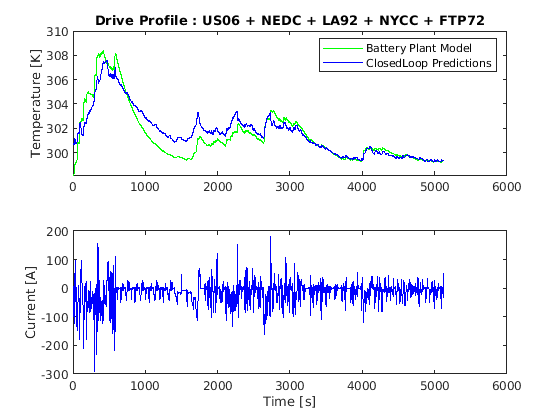

% Evaluate Profile : US06 + NEDC + LA92 + NYCC + FTP72
driveProfile_X=load('Battery_TempPredUsingNN_US06_NEDC_LA92_NYCC_FTP72.mat');
[plotData1,...
 plotData2,...
 plotData3,...
 p3,Pi3,Ai3,t3] = Battery_TempPredUsingNN_driveProfile(...
                  simulationParam,...
                  driveProfile_X,...
                  alpha);
figure(3)
subplot(2,1,1)
plot(plotData1(1,:),plotData1(2,:),'g');
hold on
plot(plotData2(1,:),plotData2(2,:),'b');
hold off
ylabel('Temperature [K]')
legend('Battery Plant Model','ClosedLoop Predictions','Location','northeast');
title('Drive Profile : US06 + NEDC + LA92 + NYCC + FTP72');
subplot(2,1,2)
plot(plotData3(1,:),plotData3(2,:),'b');
ylabel('Current [A]')
xlabel('Time [s]')

(3) WLTPclass1, WLTPclass2, WLTPclass3, US06, NEDC drive profiles run continuously one after another

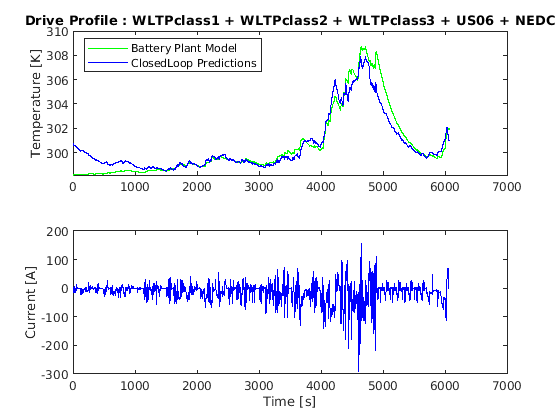

% Evaluate Profile : WLTPclass1 + WLTPclass2 + WLTPclass3 + US06 + NEDC
driveProfile_X=load('Battery_TempPredUsingNN_WLTP1_WLTP2_WLTP3_US06_NEDC.mat');
[plotData1,...
 plotData2,...
 plotData3,...
 p3,Pi3,Ai3,t3] = Battery_TempPredUsingNN_driveProfile(...
                  simulationParam,...
                  driveProfile_X,...
                  alpha);
figure(4)
subplot(2,1,1)
plot(plotData1(1,:),plotData1(2,:),'g');
hold on
plot(plotData2(1,:),plotData2(2,:),'b');
hold off
ylabel('Temperature [K]')
legend('Battery Plant Model','ClosedLoop Predictions','Location','northwest');
title('Drive Profile : WLTPclass1 + WLTPclass2 + WLTPclass3 + US06 + NEDC');
subplot(2,1,2)
plot(plotData3(1,:),plotData3(2,:),'b');
ylabel('Current [A]')
xlabel('Time [s]')

All the 3 different composite drive-profile simulations show a good predictive capability from the neural network model. The model is now ready for code generation.

# Code Generation & Deployment

## Create MATLAB function

To generate a C code from the neural network, use the **genFunction **function. 

genFunction(useNetwork,'Battery_TempPredUsingNN_NARX','MatrixOnly','yes');

 
MATLAB function generated: Battery_TempPredUsingNN_NARX.m
To view generated function code: edit Battery_TempPredUsingNN_NARX
For examples of using function: help Battery_TempPredUsingNN_NARX
 


mat_p3=cell2mat(p3);   % Convert cell arrays to matrix
mat_Pi3=cell2mat(Pi3);
mat_Ai3=cell2mat(Ai3);
y4=Battery_TempPredUsingNN_NARX(mat_p3,mat_Pi3,mat_Ai3(end,:));

Next, use **codegen** to generate the desired C code.

mat_p3_type=coder.typeof(double(0),[2,inf]);
mat_Pi3_type=coder.typeof(double(0),[2,3]);
mat_Ai3_type=coder.typeof(double(0),[1,3]);
codegen Battery_TempPredUsingNN_NARX.m -config:mex -o Battery_TempPredUsingNN_codeGen -args {mat_p3_type,mat_Pi3_type,mat_Ai3_type}
y5=Battery_TempPredUsingNN_codeGen(mat_p3,mat_Pi3,mat_Ai3(end,:));

To visualize the performance of the Matlab function and the generated C code, at the MATLAB command prompt, enter:

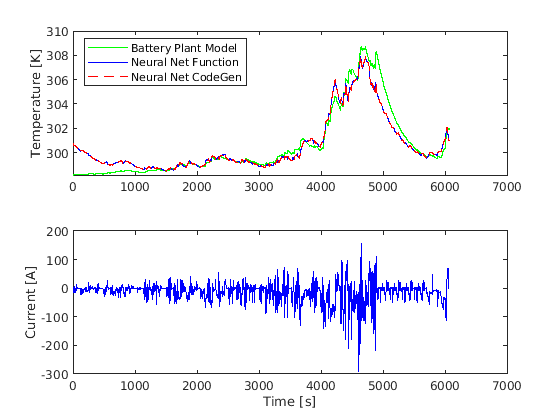

% Plot
lenSeries=max(size(driveProfile_X.validate_X.Data));
TS=size(t3,2);
figure(5);
subplot(2,1,1)
plot(1:lenSeries,driveProfile_X.validate_X.Data(1:lenSeries,2)','g');
hold on
plot(1:TS,y4.*sig_tmp+mu_tmp+tempRef,'b');
hold on
plot(1:TS,y5.*sig_tmp+mu_tmp+tempRef,'r--');
hold off
ylabel('Temperature [K]')
legend('Battery Plant Model','Neural Net Function','Neural Net CodeGen','Location','northwest');
subplot(2,1,2)
plot(1:lenSeries,driveProfile_X.validate_X.Data(1:lenSeries,1)','b')
ylabel('Current [A]')
xlabel('Time [s]')

## Deployment on Hardware

To generate a Simulink block diagram of a neural network use the function **gensim**

gensim(trainedNet{1,1})

ans = 'untitled'

The generated Simulink model has been tested on a Speedgoat Performance real-time target machine with an Intel(R) 3.5 GHz i7 multi-core CPU. You can refer to [Creating and Running Real-Time Applications | R2020b Tutorials ? Speedgoat](https://www.speedgoat.com/knowledge-center/simulink-real-time-basics/r2020b-slrt-part-3) for more on hardware deployment.